close all;
clc;

## User Input

modelName = 'HRTIM_main';

% Simulation time in seconds
sim_time_sec = 120e-6;

% Opens the simulink sim graphically if true
open_sim = true;


## Load Variables

% Load sim variables
HRTIM_simulink_var;

out_params = 6×3 table
             Parameter              Value    Unit 
    ____________________________    _____    _____

    "Primary resonant frequency"     264     "kHz"
    "Max tracked freq"               277     "kHz"
    "Min tracked freq"               198     "kHz"
    "Lead time"                        5     "ns" 
    "PRF frequency"                  200     "Hz" 
    "PRF DC"                           1     "%"  


## Run Sim

% Open model graphically
if open_sim == true
    open_system(modelName); 
end

% Create the SimulationInput object
simIn = Simulink.SimulationInput(modelName);

% Specify the StartTime and StopTime (values must be passed as strings)
simIn = setModelParameter(simIn, 'StartTime', '0', 'StopTime', string(sim_time_sec));

% Run the simulation
simOut = sim(simIn);


## Process Results

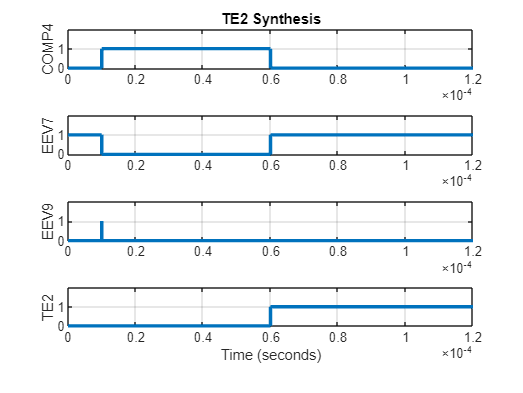

lineWidth = 2.0;

figure();

% COMP4
sp = subplot(4,1,1);
plot(simOut.COMP4_Out, "LineWidth",lineWidth);
ylim([0 2]);
yticks([0 1]);
ylabel('COMP4');
title('TE2 Synthesis')
%sp.Title.Visible = 'off';
xlabel('');
grid on;

% EEV7
sp = subplot(4,1,2);
plot(simOut.EEV7, "LineWidth",lineWidth);
ylim([0 2]);
yticks([0 1]);
ylabel('EEV7');
sp.Title.Visible = 'off';
xlabel('');
grid on;

% EEV9
sp = subplot(4,1,3);
plot(simOut.EEV9,"LineWidth",lineWidth);
ylim([0 2]);
yticks([0 1]);
ylabel('EEV9');
sp.Title.Visible = 'off';
xlabel('');
grid on;

% TE2
sp = subplot(4,1,4);
plot(simOut.TE2,"LineWidth",lineWidth);
ylim([0 2]);
yticks([0 1]);
ylabel('TE2');
sp.Title.Visible = 'off';
grid on;